% Load CSV
T = readtable('NASA_TLX.csv');

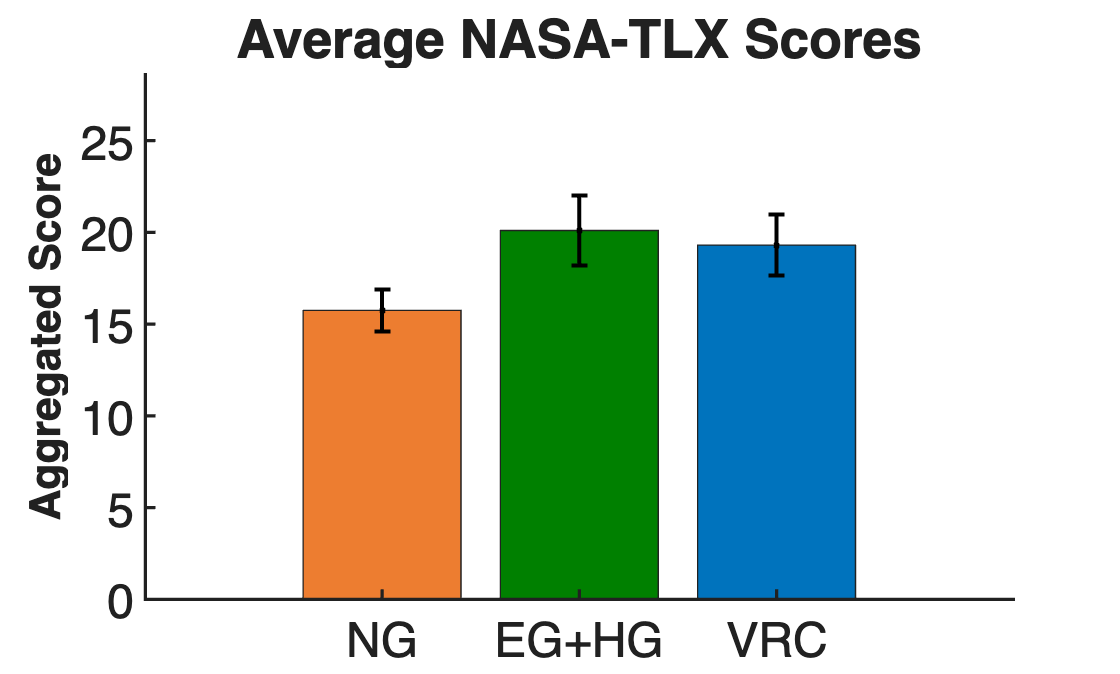


% Extract relevant columns (edit names if different)
ng  = T.NG;
eg  = T.("EG_HG");
vrc = T.VRC;

% Compute statistics
means = [mean(ng) mean(eg) mean(vrc)];
sems  = [std(ng)/sqrt(length(ng)) ...
         std(eg)/sqrt(length(eg)) ...
         std(vrc)/sqrt(length(vrc))];

% Create bar plot
figure;
b = bar(means, 'FaceColor', 'flat');
b.CData = [0.93 0.49 0.19;   % orange NG
           0.00 0.50 0.00;   % green EG+HG
           0.00 0.45 0.74];  % blue VRC

hold on
errorbar(1:3, means, sems, 'k.', 'LineWidth', 1.5);

% Axis formatting
set(gca, 'XTick', 1:3, 'XTickLabel', {'NG', 'EG+HG', 'VRC'}, ...
    'FontSize', 18, 'LineWidth', 1.2);
ylabel('Aggregated Score', 'FontSize', 16, 'FontWeight', 'bold');
title('Average NASA-TLX Scores', 'FontSize', 20, 'FontWeight', 'bold');
ylim([0 max(means+sems)*1.3]);
box off
set(gcf, 'Color', 'w');

% Export
exportgraphics(gcf, 'NASA_TLX.tiff', 'Resolution', 600);

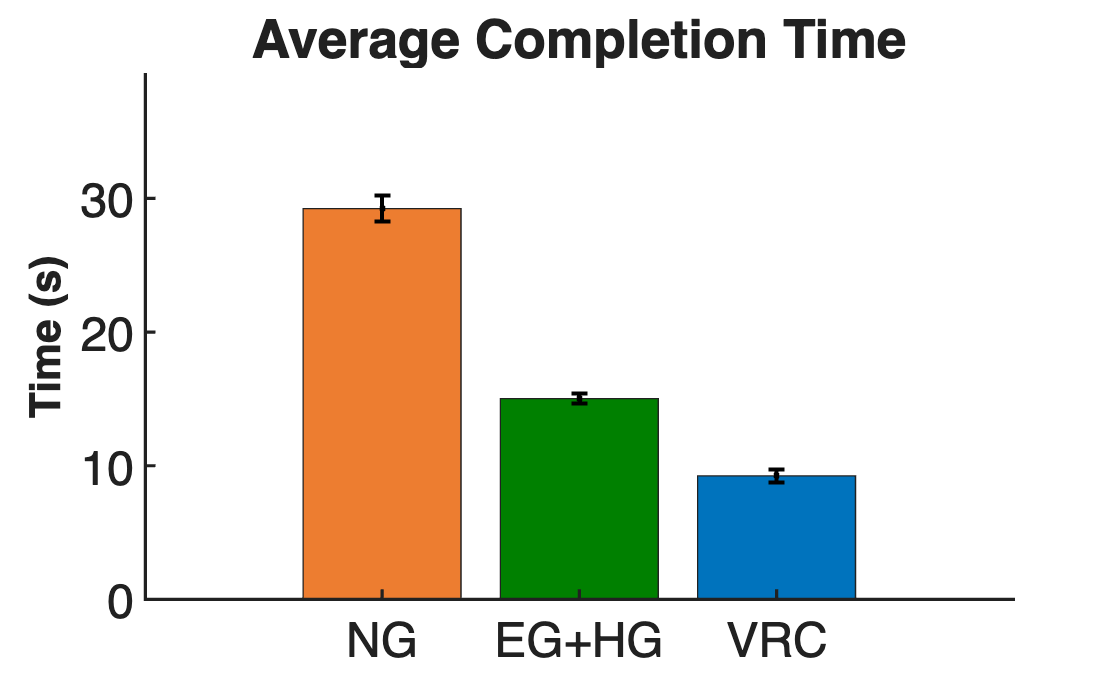

% Load CSV
T = readtable('sorted_avg_task_completion_time.csv');

% Extract relevant columns (edit names if different)
ng  = T.NG;
eg  = T.("EG_HG");
vrc = T.VRC;

% Compute statistics
means = [mean(ng) mean(eg) mean(vrc)];
sems  = [std(ng)/sqrt(length(ng)) ...
         std(eg)/sqrt(length(eg)) ...
         std(vrc)/sqrt(length(vrc))];

% Create bar plot
figure;
b = bar(means, 'FaceColor', 'flat');
b.CData = [0.93 0.49 0.19;   % orange NG
           0.00 0.50 0.00;   % green EG+HG
           0.00 0.45 0.74];  % blue VRC

hold on
errorbar(1:3, means, sems, 'k.', 'LineWidth', 1.5);

% Axis formatting
set(gca, 'XTick', 1:3, 'XTickLabel', {'NG', 'EG+HG', 'VRC'}, ...
    'FontSize', 18, 'LineWidth', 1.2);
ylabel('Time (s)', 'FontSize', 16, 'FontWeight', 'bold');
title('Average Completion Time', 'FontSize', 20, 'FontWeight', 'bold');
ylim([0 max(means+sems)*1.3]);
box off
set(gcf, 'Color', 'w');

% Export
exportgraphics(gcf, 'avg_completion_time.tiff', 'Resolution', 600);

% Load CSV
T = readtable('gross_error_rate.csv');

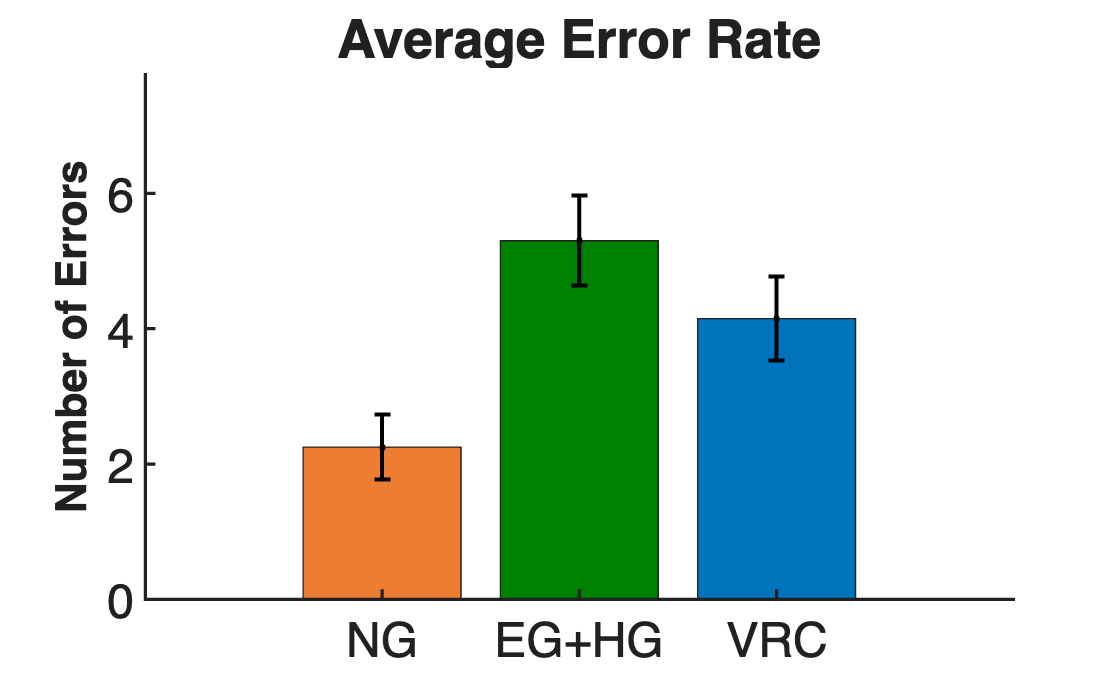


% Extract relevant columns (edit names if different)
ng  = T.NG;
eg  = T.("EG_HG");
vrc = T.VRC;

% Compute statistics
means = [mean(ng) mean(eg) mean(vrc)];
sems  = [std(ng)/sqrt(length(ng)) ...
         std(eg)/sqrt(length(eg)) ...
         std(vrc)/sqrt(length(vrc))];

% Create bar plot
figure;
b = bar(means, 'FaceColor', 'flat');
b.CData = [0.93 0.49 0.19;   % orange NG
           0.00 0.50 0.00;   % green EG+HG
           0.00 0.45 0.74];  % blue VRC

hold on
errorbar(1:3, means, sems, 'k.', 'LineWidth', 1.5);

% Axis formatting
set(gca, 'XTick', 1:3, 'XTickLabel', {'NG', 'EG+HG', 'VRC'}, ...
    'FontSize', 18, 'LineWidth', 1.2);
ylabel('Number of Errors', 'FontSize', 16, 'FontWeight', 'bold');
title('Average Error Rate', 'FontSize', 20, 'FontWeight', 'bold');
ylim([0 max(means+sems)*1.3]);
box off
set(gcf, 'Color', 'w');

% Export
exportgraphics(gcf, 'num_errors.tiff', 'Resolution', 600);